## Lectura capas de suramerica

----Reading layers----


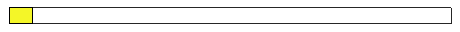

Elapsed time is 12.581324 seconds.


addpath Tool/VirtualSpeciesFunctions/
addpath Tool/
layerfolder = "Capas/Capas_SouthAmerica_2.5M/"; %route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

## Creación especie virtual con parámetros predefinidos por el usuario

close all
N = 1; %Numero de especies a crear
Sample = 200;
Alpha = 2;
Occ = 0.7;

disp("alpha:" + Alpha + ", " + "Samples:" + Sample + ", " +  "Occupation:" + Occ)

alpha:2, Samples:50, Occupation:0.7


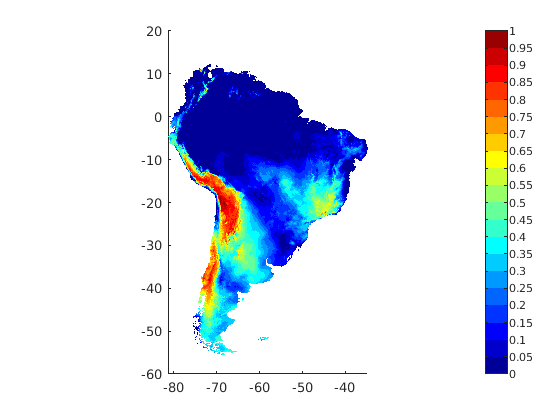

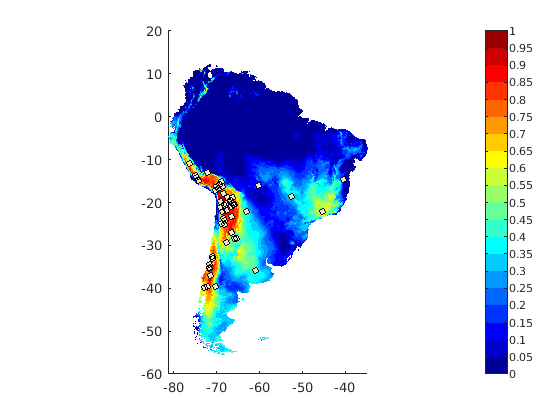

Size = Dimensions.Dimensions(2);
p = sobolset(Size);
p = scramble(p, 'MatousekAffineOwen');
Points = net(p, N);

p = sobolset(Size);
p = scramble(p, 'MatousekAffineOwen');
Coeffs = net(p, N);

showVirtual = false;
showModel = false;

Roc = zeros(length(Sample), N); 
AreaMetric = zeros(length(Sample), N);
DistanceMetric = zeros(length(Sample), N);
InfoInitialPoint = cell(N, 1);

InfoInitialPoint = InitialPoint(Dimensions, Points', Coeffs');

showVirtual = true; 
% T2=[];

for i = 1 : N
    figure
    InfoInitialPoint= InitialPoint(Dimensions, Points(i, :)', Coeffs(i, :)');
    MapInfo = VirtualSpecies(Dimensions, InfoInitialPoint, Occ, showVirtual);
    figure
    NicheMap = MapInfo.Map;
    T = samplingVS(Dimensions, MapInfo, Sample, Alpha, showVirtual, 'GenSP_' + string(i), true, true);
%     T2 = [T2;T];
%     writetable(T,"virtualBest_" + num2str(i) + '.csv');
    drawnow
end


% writetable(T2,"CasesVS/virtualBest.csv");
% save("Clustering", "T", "NicheMap")

## Creación especie virtual usando datos del peor caso 

PointsAll = [];
CoeffsAll = [];
DistanceAll = [];
AreaMetricAll = [];
RocAll = [];

for i = 1 : 4
    load("OLDMODEL/Test/2_5KM/Test" + num2str(i) + "_SA_25_NoAlpha.mat")
    PointsAll = [PointsAll; Points];  
    CoeffsAll = [CoeffsAll; Coeffs];
    DistanceAll = [DistanceAll, DistanceMetric];
    AreaMetricAll = [AreaMetricAll, AreaMetric];
    RocAll = [RocAll, Roc];
end

Points = PointsAll;
Coeffs = CoeffsAll;
Distance = DistanceAll;
AreaMetric = AreaMetricAll;
Roc = RocAll;

clear PointsAll CoeffsAll DistanceMetricAll AreaMetricAll RocAll

close all
N = 1; %Numero de especies a crear

WC = 13;

disp("alpha:" + alpExp(WC) + ", " + "Samples:" + SampExp(WC) + ", " +  "Occupation:" + OccupExp(WC))

alpha:2, Samples:10, Occupation:0.7


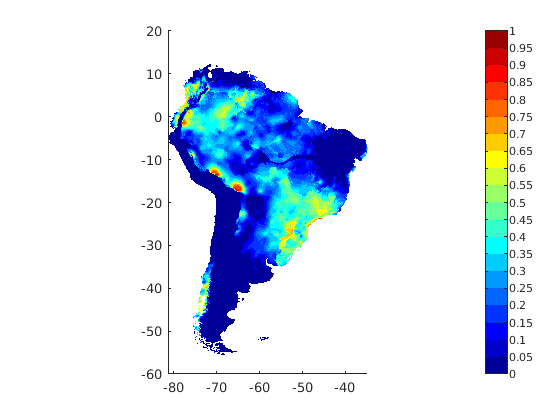

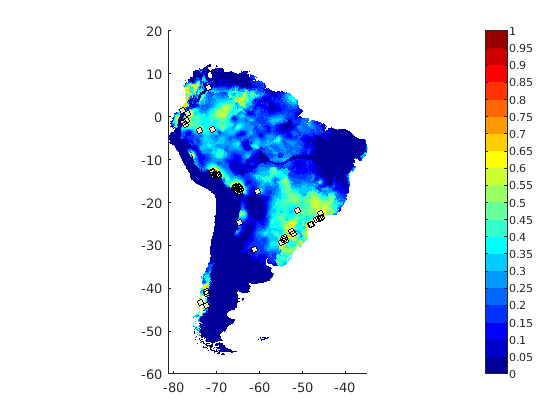


% RN = randi([1 1000],[N, 1]);
load('/home/curie/MATLAB-Drive/VirtualSpecies/OLDMODEL/CasesVS/WorstSelectedMapsBC.mat')
showVirtual = true; 
T2 = [];


for i = 1 : N
    figure
    j = RN(i);
    InfoInitialPoint= InitialPoint(Dimensions, Points(j, :)', Coeffs(j, :)');
    MapInfo = VirtualSpecies(Dimensions, InfoInitialPoint, OccupExp(WC), showVirtual);
    NicheMap = MapInfo.Map;
    figure
    T = samplingVS(Dimensions, MapInfo, 500, alpExp(WC), showVirtual,'GenSP_' + string(i), true, true);
%     T2 = [T2;T];
%     drawnow
end